Assignment 1

As its not realistic to 'sing' at 1000Hz for me i will instead do my best and see how high i can get and adjust the clean signal accordingly. I think my dear collegue will get the gist anyways.

clc;
clear;
% Reading audio file of me singing as high as i can
path_2_wav = 'C:\Users\admin\Documents\MEGA\DTU\DSP\asHighAsICanGet.wav';    % the path to the data
[y, fs_y] = audioread(path_2_wav);

% Use only the first channel (discard the second channel since its a mono
% recording)
y = y(:, 1);

% lets check the frequency by making a FFT plot, with frequency (Hz) and
% magnitude (dB) on respectively the x-axis and y-axis.

% Calculate the FFT
N_fft = length(y);                 % Length of the signal (we know its been recorded at 44100 Hz)
Y_fft = fft(y);               % FFT of the audio signal

% Calculate frequency vector
f_fft = 0:N_fft-1;     % Frequency vector in Hz

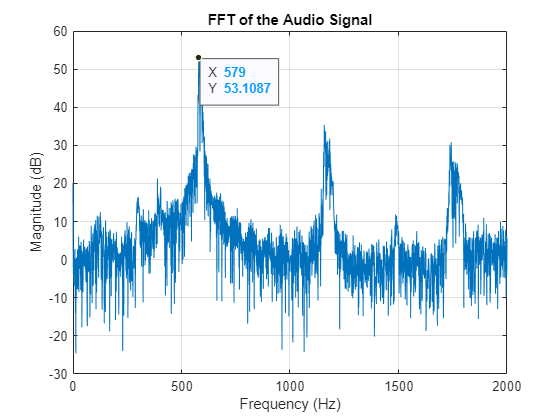

% Compute magnitude in dB
magnitudeY_dB = 20*log10(abs(Y_fft)); 

% Plot the FFT (Magnitude Spectrum in dB)
figure;
plot(f_fft, magnitudeY_dB); 
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FFT of the Audio Signal');
grid on;
xlim([0 2000])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,579,53.11);

As seen on the FFT my peak singing frequency is at about 579 Hz. We will adjust the clean signal accordingly.

Now lets plot a clean signal that is 579 Hz.

f = 579;

% The plot on the paper (paperplot) is gone beyond 3000Hz, so the sampling
% freq is not completely clear. But since its specified that its recorded with
% standard equipment, the sampling rate is probably 44.1 kHz
fs = 44100; % Sampling frequency (Hz)
T = 1/fs; % Sampling period (s)

% Vector with 44100 points spaced T seconds apart
t = 0:T:1-T; % Time vector for 1s

% Generate the cosine wave
clean_signal = cos(2 * pi * f * t);


Lets plot the audio signal

% Start by using a moving average filter to smooth the noise
% Define the moving average filter window size (the larger, the smoother)
windowSize = 10;  % Adjust this value to control the smoothness

% Create the moving average filter kernel
b = ones(1, windowSize) / windowSize;  % The kernel for moving average

% Apply the moving average filter using convolution
y_smoothed = conv(y, b, 'same');  % 'same' keeps the output the same length as the input


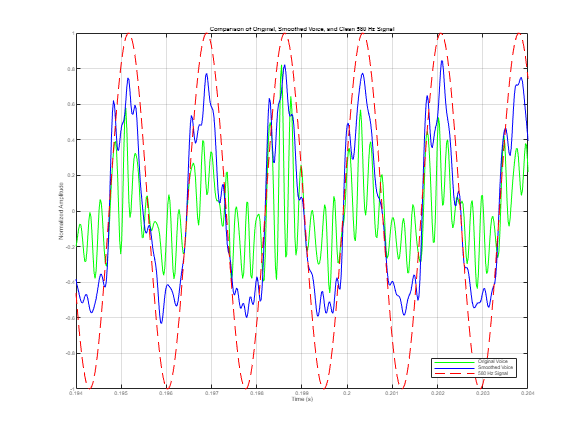

% Normalize the original, smoothed, and clean signals
y_normalized = y / max(abs(y));  % Normalize the original voice signal
y_smoothed_normalized = y_smoothed / max(abs(y_smoothed));  % Normalize the smoothed voice signal
clean_signal_normalized = clean_signal / max(abs(clean_signal));  % Normalize the clean signal

% Plot the original, smoothed, and clean signals together
figure('Name', 'Comparison Plot', 'Position', [400, 300, 800, 600]);

% Set papersize for export
set(gcf, 'PaperUnits', 'centimeters', 'PaperPosition', [0 0 10 4]);
plot(t, y_normalized, 'g');  % Plot the normalized original voice signal in green
hold on;
plot(t, y_smoothed_normalized, 'b');  % Plot the normalized smoothed voice signal in blue
plot(t, clean_signal_normalized, 'r--');  % Plot the normalized clean cosine wave in red dashed line

% Label the plot
set(gca, 'FontSize', 4);  % Adjust font size
title('Comparison of Original, Smoothed Voice, and Clean 580 Hz Signal');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
legend('Original Voice', 'Smoothed Voice', '580 Hz Signal','Location','southeast');
grid on;
xlim([0.194 0.204]);  % Zoom in on a small section of the plot for clearer comparison
hold off;


%saveas(gcf, 'time_domain_plot.eps', 'psc2');
%print(gcf, 'time_domain_plot.png', '-dpng', '-r600');  % Save as PNG with 600 DPI
%exportgraphics(gcf,'vectorfig.eps','ContentType','vector')

Now its time to convert this into the frequency domain.

To reproduce the plot, so the individual samples are 2Hz apart we'll adjust the resolution using the formula:

delta_f = f_s / N, 

where | delta_f: frequency resolution, f_s: sample frequency and N: Number of points for the FFT

--> N =f_s/delta_f = 44100/2 = 22050

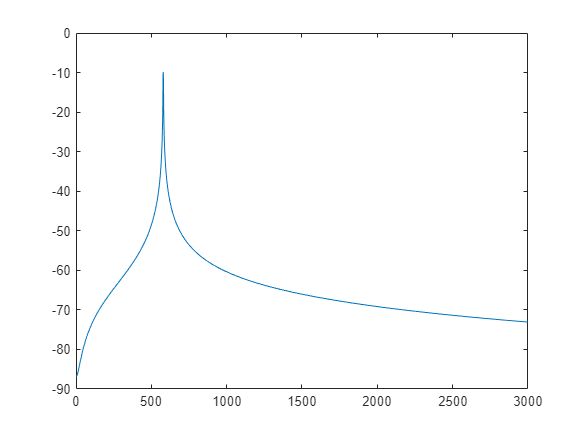

clf;

% v2
N = 22050;
clean_signal_fft = fft(clean_signal, N);

% normalize the fft with the sample size
clean_signal_fft_norm = abs(clean_signal_fft) / N;

f_fft = (0:N-1) * (fs / N); 

plot(f_fft,20*log10(clean_signal_fft_norm))
xlim([0 3000])
hold on 
% plot clean signal where the normalization in done before fft
%clean_signal_normalized = abs(clean_signal) / N;
%clean_signal_normalized_fft = fft(clean_signal_normalized, N);
%plot(f_fft,20*log10(abs(clean_signal_normalized_fft)))
% Is very much not what we were looking for

% audio signal
%y_fft = fft(y, N);

% normalize sample size
%y_fft_norm = abs(y_fft) / N;
%plot(f_fft,20*log10(y_fft_norm));


























% Normalize both signals before FFT computation
y_normalized = y / max(abs(y));  % Normalize the original audio signal
clean_signal_normalized = clean_signal / max(abs(clean_signal));  % Normalize the clean signal

% Calculate the FFT of the normalized clean 579 Hz signal with 22050 points (2 Hz resolution)
N = 22050;  % Number of points for the FFT to achieve 2 Hz resolution
clean_signal_fft = fft(clean_signal, N);  % FFT of the clean signal

% Normalize with the sample size
clean_signal_fft_normalized = abs(clean_signal_fft) / N

clean_signal_fft_normalized =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002



% Frequency vector 
f_fft = (0:N-1) * (fs / N); 

% Compute magnitude in dB for the clean signal FFT
magnitude_clean_signal_dB = 20*log10(abs(clean_signal_fft_normalized)); 

% Recalculate the FFT of the normalized audio signal with 22050 points for matching resolution
Y_fft_resized = fft(y, N);  % Recalculate FFT with the new N

% Normalize audio 
Y_fft_resized_normalized = abs(Y_fft_resized) / N

Y_fft_resized_normalized =     0.0002
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


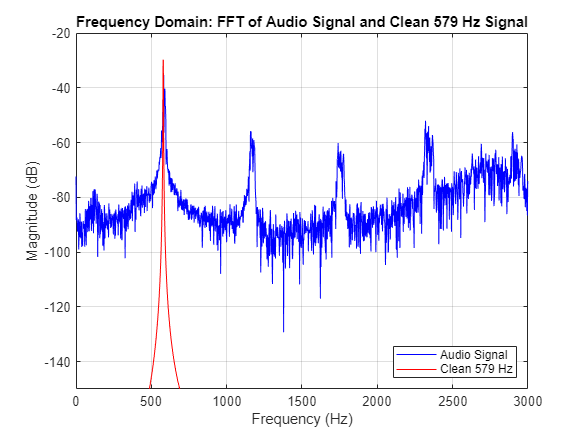


% Compute magnitude in dB for the resized audio FFT
magnitudeY_dB_resized = 20*log10(abs(Y_fft_resized_normalized));  

% Plot both FFTs together for comparison with the same dimensions and font size
figure('Name', 'FFT Comparison', 'Position', [400, 300, 800, 600]);  % Same figure size
set(gcf, 'PaperUnits', 'centimeters', 'PaperPosition', [0 0 10 4]);  % Same paper size for export

% Plot FFT of the audio signal in blue
plot(f_fft, magnitudeY_dB_resized, 'b');  
hold on;

% Plot FFT of the clean signal in red
plot(f_fft, magnitude_clean_signal_dB*3, 'r');  % added a scaling factor, to make the clean signal more distinctly show its peak 

% Label the plot
set(gca, 'FontSize', 10);  % Same font size
title('Frequency Domain: FFT of Audio Signal and Clean 579 Hz Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Audio Signal', 'Clean 579 Hz', 'Location', 'southeast');
grid on;
xlim([0 3000]);  % Limit the x-axis to show frequencies up to 3000 Hz
ylim([-150 -20]); 
hold off;


% Save the figure as PNG with 600 DPI, matching previous settings
%print(gcf, 'fft_comparison_plot.png', '-dpng', '-r600');



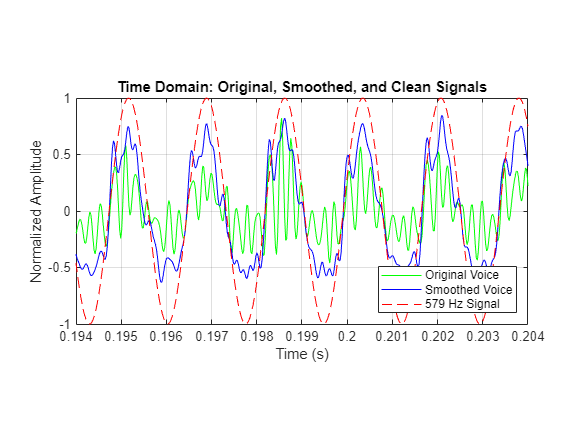

% Reading audio file of me singing as high as I can
path_2_wav = 'C:\Users\admin\Documents\MEGA\DTU\DSP\asHighAsICanGet.wav';  % Path to the data
[y, fs_y] = audioread(path_2_wav);  % Read the audio file

% Use only the first channel (since it's mono)
y = y(:, 1);

% Define the clean signal (579 Hz sine wave)
f = 579;  % Frequency of the clean signal
t = (0:length(y)-1) / fs_y;  % Time vector

% Generate the clean 579 Hz cosine wave for comparison
clean_signal = cos(2 * pi * f * t);

% Moving average filter (to smooth the voice signal)
windowSize = 10;  % Adjust this value to control the smoothing
b = ones(1, windowSize) / windowSize;  % Create the moving average filter kernel
y_smoothed = conv(y, b, 'same');  % Apply the moving average filter

% Normalize the original, smoothed, and clean signals
y_normalized = y / max(abs(y));  % Normalize the original voice signal
y_smoothed_normalized = y_smoothed / max(abs(y_smoothed));  % Normalize the smoothed voice signal
clean_signal_normalized = clean_signal / max(abs(clean_signal));  % Normalize the clean signal

% Plot: Time-Domain Plot
figure('Name', 'Time Domain Plot', 'Position', [400, 300, 800, 600]);
plot(t, y_normalized, 'g');  % Plot the normalized original voice signal in green
hold on;
plot(t, y_smoothed_normalized, 'b');  % Plot the normalized smoothed voice signal in blue
plot(t, clean_signal_normalized, 'r--');  % Plot the normalized clean cosine wave in red dashed line
pbaspect([2 1 1])
% Label the time-domain plot
set(gca, 'FontSize', 10);  % Same font size for consistency
title('Time Domain: Original, Smoothed, and Clean Signals');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
legend('Original Voice', 'Smoothed Voice', '579 Hz Signal', 'Location', 'southeast');
grid on;
xlim([0.194 0.204]);  % Zoom in on a small section of the plot for clearer comparison
hold off;

% Save the plot as EPS and PNG formats
print(gcf, 'time_domain_plot.eps', '-depsc');  % Save as EPS
print(gcf, 'time_domain_plot.png', '-dpng', '-r600');  % Save as PNG with 600 DPI

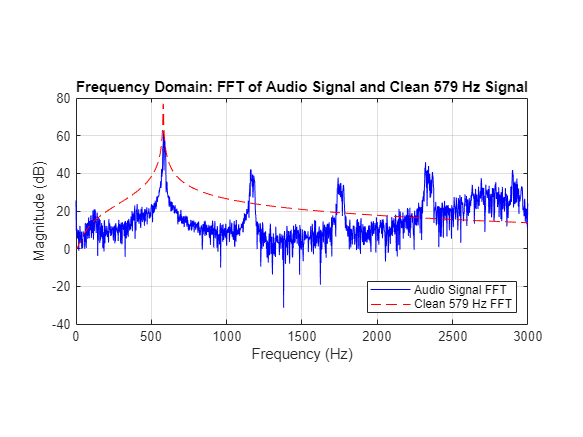

% Reading audio file of me singing as high as I can
path_2_wav = 'C:\Users\admin\Documents\MEGA\DTU\DSP\asHighAsICanGet.wav';  % Path to the data
[y, fs_y] = audioread(path_2_wav);  % Read the audio file

% Use only the first channel (since it's mono)
y = y(:, 1);

% Define the clean signal (579 Hz sine wave)
f = 579;  % Frequency of the clean signal
t = (0:length(y)-1) / fs_y;  % Time vector

% Generate the clean 579 Hz cosine wave for comparison
clean_signal = cos(2 * pi * f * t);

% Normalize the original and clean signals
y_normalized = y / max(abs(y));  % Normalize the original voice signal
clean_signal_normalized = clean_signal / max(abs(clean_signal));  % Normalize the clean signal

% Frequency-Domain Analysis
N = 22050;  % Number of points for the FFT to achieve 2 Hz resolution
y_fft = fft(y_normalized, N);  % FFT of the normalized original audio signal
clean_signal_fft = fft(clean_signal_normalized, N);  % FFT of the clean signal

% Frequency vectors for both FFTs
f_fft = (0:N-1) * (fs_y / N);  % Frequency vector for both signals

% Compute magnitudes in dB
magnitude_y_fft_dB = 20*log10(abs(y_fft) + eps);  % Avoid log(0)
magnitude_clean_signal_fft_dB = 20*log10(abs(clean_signal_fft) + eps);  % Avoid log(0)

% Plot: Frequency-Domain Plot
figure('Name', 'Frequency Domain Plot', 'Position', [400, 300, 800, 600]);
plot(f_fft, magnitude_y_fft_dB, 'b');  % Plot FFT of the audio signal
hold on;
plot(f_fft, magnitude_clean_signal_fft_dB, 'r--');  % Plot FFT of the clean signal
pbaspect([2 1 1])

% Label the frequency-domain plot
set(gca, 'FontSize', 10);  % Same font size
title('Frequency Domain: FFT of Audio Signal and Clean 579 Hz Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Audio Signal FFT', 'Clean 579 Hz FFT', 'Location', 'southeast');
grid on;
xlim([0 3000]);  % Limit the x-axis to show frequencies up to 2000 Hz
hold off;

% Save the plot as EPS and PNG formats
print(gcf, 'frequency_domain_plot.eps', '-depsc');  % Save as EPS
print(gcf, 'frequency_domain_plot.png', '-dpng', '-r600');  % Save as PNG with 600 DPI